# **Heater Band Zone 1 Simulation**

This is a pre-simulation without truly knowing the plant transfer function of the system. Using the System Identification Toolbox, we should be able to derive an accurate plant model for each zone. To achieve this, we should consider running the system in manual mode at ~25% output power for approximately 10-15 minutes, so long as the heaters do not heat up too much. With this new plant model, assuming it is accurate, we will no longer need to account for any physical system properties such as thermal mass, thermal time constants, wattage, etc. We also should not need to account for airflow disturbance as it will be part of the plant function.

clear all
clc
close all

## Data Section

Data is either calculated or arbitraily chosen based on testing. 'Tinitial', 'time', and 'setpt' will stay the same in the next stage of simulation once we determine a true plant function.

Note Pertaining to **Line 13**: Tau was initially selected to be 165 seconds. What I did was measure it at 195°C on the compensated physical system, which was not correct. What should have been done was to see how long it took for the temperature to reach 195°C with the controller set in manual mode at 100% power. However, this measurement can still be used in the simulation to compare to what was seen on the physical system. To get an accurate number, tau was adjusted to get as close as possible to the time measurement of 195°C at 167 seconds, with 1°C of overshoot. Right now with tau = 68, the system reaches 195°C in 156 seconds, with 1°C of overshoot. This can be further refined however, as the system does not yet compensate for active cooling. 

**Aside: Airflow is 2 m/s**

s = tf('s'); % creates special variable 's' that can be used to create a transfer function model
time = 800; % elapsed time (secs), 12 mins
w = 250; % setpoint, °C
x = 100; % initial temp of zone, °C

% variables below are only needed for this specific sim.
ssT = x + 0.632 * (w - x); % 63.2% Steady State Temperature Change
power = 2000; % heater wattage, W
tau = 68; % thermal time constant
tau_null = 167; % thermal time constant for compensated closed-loop system

## Plant Model and Simulation of the Plant Function

The plant model shown below is from classical control theory. It is a first order heater. This is not entirely accurate because I am unsure what order this system is, but works for the time being.

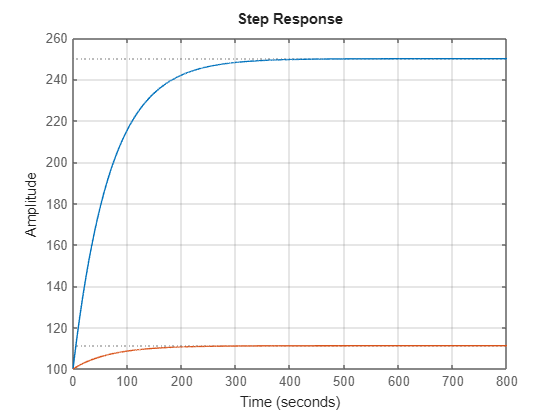

% The plant model shown below is from classical control theory. It is a 
% first order heater. Further testing will need to be done to determine the
% order of the system based on SQL data.

% Open-Loop Gain
K = (w - x)/power; % °C/W, for every watt of heat dissipated, the temperature will rise by 'K'

% Plant Transfer Function
Gp = K/(tau*s+1); % first order thermal system (Classical Controls)
t = 0:0.1:time;  % Time vector (seconds), 0.1s time step

figure(1)

step(Gp * power + x, t); % simulated open loop step response

hold on

Gcl_unc = feedback(Gp, 1); % uncompensated closed-loop feedback
step(Gp * (w - x) + x, t); % uncompensated closed loop step response

hold on
grid on

## Controller Implementation and Parameters

PID Parameters for this specific heater zone are pulled from what is input on the PLC. For future reference, zones 1 through 8 have been included, but commented out.

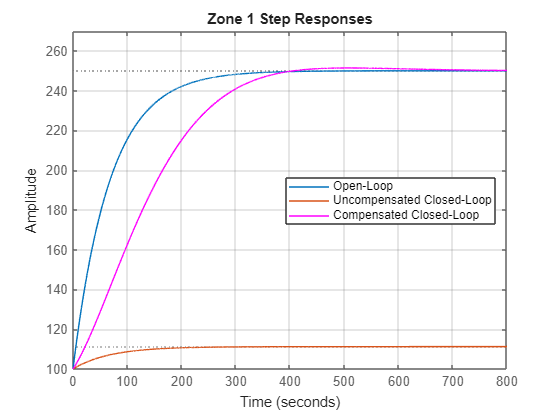

% PID Parameters Zone 1 for AMC 160
Kp = 10; % proportional gain
Td = 25; % derivative time delay
Ti = 100; % integral action time delay
ts = 2; % sampling time
a = 0.1; % coefficient for derivative-action delay, not very sure what this does and needs more research
c = 0; % derivative action weighting
b = 2.5211000E-01; % proportional action weighting

% Siemens Controller Implementation - pidstd2() command does the same thing
Gc = Kp*(b + 1/(Ti*s) + (Td*s/(a*Td*s+1))*c); % Siemens controller alg. pulled from Siemens documentation
%Gc = pidstd2(Kp, Ti, Td, a, b, c); % work on this at a later date

% the feedback function directly applies the feedback to the controller. In
% this case it is the measured temperature output.
Gcl_com = feedback(Gc*Gp, 1); % compensated system feedback

sp = stepplot(Gcl_com * (w - x) + x, t, 'm'); % simulated step input for compensated system
title("Zone 1 Step Responses")
legend("Open-Loop", "Uncompensated Closed-Loop", "Compensated Closed-Loop", Location="east")
xlim([0 time]);
ylim([100 w+20]);

## PID Tuning Section

This section shows the compensated closed loop response. this is what will be used when tuning the PID in this simulation. the previous plots are meant for evaluation. to change the plot, you will have to adjust the PID values in the previous section labeled as "Controller Implementation and Parameters"

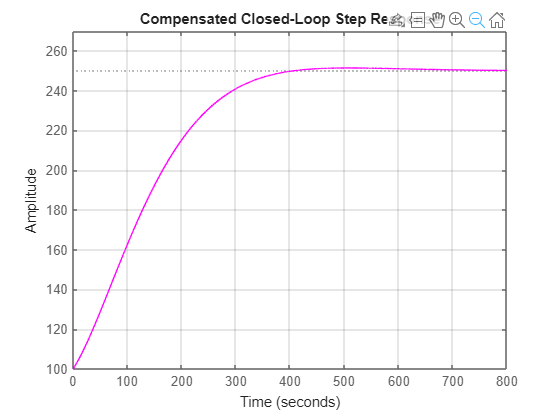

figure(2)
Gcl_com = feedback(Gc*Gp, 1); % compensated system feedback
step(Gcl_com * (w - x) + x, t, 'm'); % simulated step input for compensated system
grid on
title("Compensated Closed-Loop Step Response")
xlim([0 time]);
ylim([100 w+20]);

## Future Use

% PID Parameters Zones 1 - 8
% Kp = [10.0, 2.512243, 2.705058, 2.902283, 2.9, 3.587241, 3.629854, 2.89523]; % proportional gain
% Td = [100.0, 99.51765, 107.6981, 98.82712, 95.0, 89.25153, 76.33755, 134.5546]; % derivative time delay
% Ti = [25.0, 25.21677, 27.25217, 25.0027, 25.0, 22.60847, 19.337365, 34.11558]; % integral action time delay
% ts = [2.5211000E-01, 2.550063E-01, 2.573011E-01, 0.25766585, 2.580306E-01, 2.555074E-01, 0.25549115, 2.540359E-01]; % sampling time
% a = 0; % coefficient for derivative-action delay
% c = 0.1; % derivative action weighting
% b = 2.5211000E-01; % proportional action weighting